# Conf Interv

In the section on Sampling and Standard Error, it was shown that we can take a sample from a population, and get a good estimate of the mean of the population. 

In the ROC section, sensitivity and specificity were examined.

In diagnostic tests, we sometimes want to be sure that we are not missing many positive cases (we dont want to tell people they are well, if they have cancer that needs further invetigation). In other words, we say that the true positive rate (TPR), or sensitivity, must be at least a certain value e.g. 90%. We want to set a high value for this, but making it too high will mean we are calling positive, people who are really negative (the false positive rate, will be too high, or equivalently, the specificity will be too low).

What is the implication of setting a Sensitiviy (TPR) of 90% when developing tests, when we can only have a limited number of people in a sample?

% Mean test score for true positive and true negative cases
meanTestPositive = 0.6 ;
meanTestNegative = 0.1 ;

% Standard deviations of test scores 
stdTestPositive = 0.3 ;
stdTestNegative = 0.05 ;

% Size of sample
numSubjects = 100 ;

% Prevalence of disease as percentage positive of the total
prevalencePercent = 20 ;

% Number of subjects truly positive and negative
numPositive = round( prevalencePercent/100 * numSubjects ) ;
numNegative = numSubjects - numPositive ;

% Code (numeric label) for true positive and negative classes
posClass = +1 ; negClass = -1 ;

Now simulate sampling, but multiple times.. 

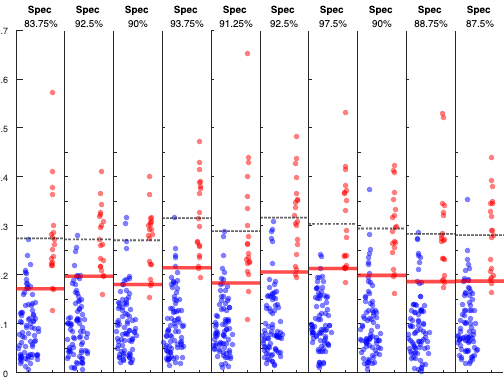

numRptSamples = 10 ;
figure(Name='Test Scores - Repeat Samples')
tl = tiledlayout(1,numRptSamples,'TileSpacing','tight','Padding','tight') ;

axesList = [] ;
setTPRprc = 90 ;

for irpt = 1: numRptSamples
    ax = nexttile(tl) ;
    axesList = [axesList ax] ; 

    % randn gives normal distribution with zero mean and std of 1.
    % scoresOfTruePositives = ( randn([numPositive 1]) * stdTestPositive ) + meanTestPositive ;
    % scoresOfTrueNegatives = ( randn([numNegative 1]) * stdTestNegative ) + meanTestNegative ;

    mu = 0.3 ; A = 10 ; B = (A/mu)-A ;
    scoresOfTruePositives = betarnd(A,B,[numPositive 1]) ;

    mu = 0.1 ; A = 2 ; B = (A/mu)-A ;
    scoresOfTrueNegatives = betarnd(A,B,[numNegative 1]) ;

    % Assign subject number to a score
    subjectNumbers = [1:numSubjects]' ;
    p = randperm(numSubjects) ;  % determine a random order of the subjects
    subjectNumbers = subjectNumbers(p) ;

    scoresTest = cat(1, scoresOfTruePositives, scoresOfTrueNegatives ) ; % concatenate scores
    scoresTest = scoresTest(p) ; % apply the order

    referenceStandard = cat(1, repmat(posClass,[numPositive 1]), repmat(negClass, [numNegative 1])) ;
    referenceStandard = referenceStandard(p) ;

    refColours = cat(1, repmat([1 0 0],[numPositive 1]), repmat([0 0 1],[numNegative 1])) ;
    refColours = refColours(p,:) ;

    swarmchart(referenceStandard, scoresTest, [], refColours, 'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    xticks([negClass posClass]), xticklabels({'',''});
    if irpt > 1
        yticklabels({}) ;
    end

    isRefP = referenceStandard==posClass ;
    TTPR90 = prctile(scoresTest(isRefP), 100-setTPRprc) ; % threshold for the pre-set TPR
    meanPositives = mean(scoresTest(isRefP)) ;
    yline(TTPR90, 'LineWidth',4,'Color',[1 0 0])
    yline(meanPositives,'LineWidth',2,'LineStyle',':')

    % See ROC notebook
    isTP = scoresTest >= TTPR90 & referenceStandard==posClass ;
    isTN = scoresTest <  TTPR90 & referenceStandard==negClass ;
    isFP = scoresTest >= TTPR90 & referenceStandard==negClass ;
    isFN = scoresTest <  TTPR90 & referenceStandard==posClass ;

    TP = sum(isTP) ; TN = sum(isTN) ; FP = sum(isFP) ; FN = sum(isFN) ;

    title("Spec ", 100*TN/(TN+FP) + "%")
end

linkaxes(axesList)

Alternativly, use a `swarmchart`. This offers a cleaner representation. Ideally we want the Test Scores for all the red positives well above the scores for the blue negatives. If that were the case, we could choose a sTest Score value between the two as the threshold operating point.  In reality, there is usually overlap and the `swarmchart` visualises how many points are in the overlapping region. 

figure(Name='Test Scores')
swarmchart(referenceStandard, scoresTest, [], refColours, 'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
title('Test Scores')
ylabel('Test score')
xticks([negClass posClass]), xticklabels({'Negative','Positive'})
grid on

It is also common to see box and whisker plots. These have the advantage of showing values such as median and interquartile range. They don't provide a very good representation of the overlap region, compared to the swarmchart above, or histograms below.

% note in this demo, it is a coincidence the automatic colours of the box chart 
% are what we want.
figure(Name="Box Chart")
x = categorical(referenceStandard,[negClass posClass],{'Negative','Positive'}) ;
b = boxchart(x, scoresTest, 'GroupByColor', referenceStandard) ;
title("Box Chart")

Finally, let's see the histograms of the data. These show the shapes of the distributions of data points in the sample. Again, we can see the overlap region, though the `swarmchart` has the advantage of showing individual data points and not bins.

% Show histograms
hPositive = histogram(scoresOfTruePositives,'Orientation','horizontal','FaceColor','r','FaceAlpha',0.6) ;
hold on, grid on
hNegative = histogram(scoresOfTrueNegatives,'Orientation','horizontal','FaceColor','b','FaceAlpha',0.6) ;

From the figures, we can see that there is an overlap region where subjects with the same test score can be true positive or true negative. It is this overlap region that determines the shape of the ROC curve and the Sensitiviy and Specificity.

To plot an ROC curve, we can use `perfcurve`.

[X,Y,T,AUC,OPTROCPT] = perfcurve(referenceStandard,scoresTest,posClass);
figure
plot(X,Y, LineWidth=2), hold on, grid on
plot([0 1],[0 1],'k--') 
xlabel('False positive rate (1 - Specificity)') , ylabel('True positive rate (Sensitivity)')
title("ROC for Binary Classification","AUC = "+AUC)

Add markers at three thresholds to highlight that the curved part depends on only the range of thresholds where test scores from the true positive and negative overlap. If there is a small number of points in that region, small changes in the score used as a threshold can lead to large changes in the ROC curve, 

thresholdA = meanTestPositive  ;
thresholdB = ( meanTestNegative + meanTestPositive ) / 2 ;
thresholdC = meanTestNegative  ;

% Find locations of these thresholds on the ROC curve
[~, iThreshA] = min(abs(T-thresholdA)) ; % location of threshold closest to thresholdA
[~, iThreshB] = min(abs(T-thresholdB)) ; 
[~, iThreshC] = min(abs(T-thresholdC)) ; 

markerArgs = { 'MarkerSize',10, 'MarkerEdgeColor','k', 'MarkerFaceColor','k'} ;
plot(X(iThreshA(1)), Y(iThreshA(1)),'ko', markerArgs{:})
text(X(iThreshA(1))+0.03, Y(iThreshA(1)), ['Threshold=',num2str(thresholdA)])

plot(X(iThreshB(1)), Y(iThreshB(1)),'go',  markerArgs{:})
text(X(iThreshB(1))+0.01, Y(iThreshB(1))-0.03, ['Threshold=',num2str(thresholdB)])

plot(X(iThreshC(1)), Y(iThreshC(1)),'ro',  markerArgs{:})
text(X(iThreshC(1)), Y(iThreshC(1))-0.05, ['Threshold=',num2str(thresholdC)])


This simulation script can be re-run to give an indication of the variability in the cure shape. In reality, we measure only one sample of limited size. A method to estimate confidence intervals is bootstrapping where the analysis is run multiple times leaving out different permutations of data.

% Use Bootstrapping in perfcurve. Note Xb,Yb and AUCb outputs have 3 columns -
% the value, its lower limit and its upper limit.
[Xb,Yb,Tb,AUCb] = perfcurve(referenceStandard,scoresTest,posClass,'NBoot', 1000);

text(0.3,0.1,"AUC = "+AUCb(1)+" ("+AUCb(2)+", "+AUCb(3)+")")

% At a pre-determined Sensitivity (y value) of 90%
yPreset = 0.9 ;
[~,itpr] = min(abs( Yb(:,1) - yPreset)) ; % itpr is index into true positive rate array Yb

ind = itpr(1) ; % In case there is more than one point equi-distant from yPreset

text(0.3,0.2,"For a Sensitivity of "+Yb(ind,1)*100 +"%, threshold is "+Tb(ind))

% errorbar(x,y,yneg,ypos,xneg,xpos)
eb = errorbar(Xb(ind,1), Yb(ind,1), Yb(ind,1)-Yb(ind,2), Yb(ind,3)-Yb(ind,1), ...
                                    Xb(ind,1)-Xb(ind,2), Xb(ind,3)-Xb(ind,1) ) ;

eb.LineWidth = 2 ; eb.Color = [1 0 0] ;

ttable = table('Size',[2 2],'VariableTypes',{'uint64','uint64'},  ...
    'VariableNames',{'Ref Positive','Ref Negative'}, ...
    'RowNames',{'Test Positive','Test Negative'}) ;

TTPR90 = Tb(ind) ; % Threshold at which Sensitivity (TPR) is 90% (see above)

isTP = scoresTest >= TTPR90 & referenceStandard==posClass ;
isTN = scoresTest <  TTPR90 & referenceStandard==negClass ;
isFP = scoresTest >= TTPR90 & referenceStandard==negClass ;
isFN = scoresTest <  TTPR90 & referenceStandard==posClass ;

TP = sum(isTP) ; TN = sum(isTN) ; FP = sum(isFP) ; FN = sum(isFN) ;

ttable.("Ref Positive") = [ TP ; FN ];
ttable.("Ref Negative") = [ FP ; TN ];

ttable

disp("Sensitivity: TPR = TP/(TP+FN) = " + TP + " / ( " + TP +" + " + FN + " ) = " + TP/(TP+FN))

disp("Specificity: TNR = 1-FPR = TN/(TN+FP) = " + TN + " / ( " + TN +" + " + FP + " ) = " + TN/(TN+FP))


Re-plot the swarmchart

figure(Name='swarmchart Test Scores')
swarmchart(referenceStandard, scoresTest, [], refColours, 'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
title('Test Scores')
ylabel('Test score')
xticks([negClass posClass]), xticklabels({'Negative','Positive'})
grid on

yl = yline(TTPR90) ;